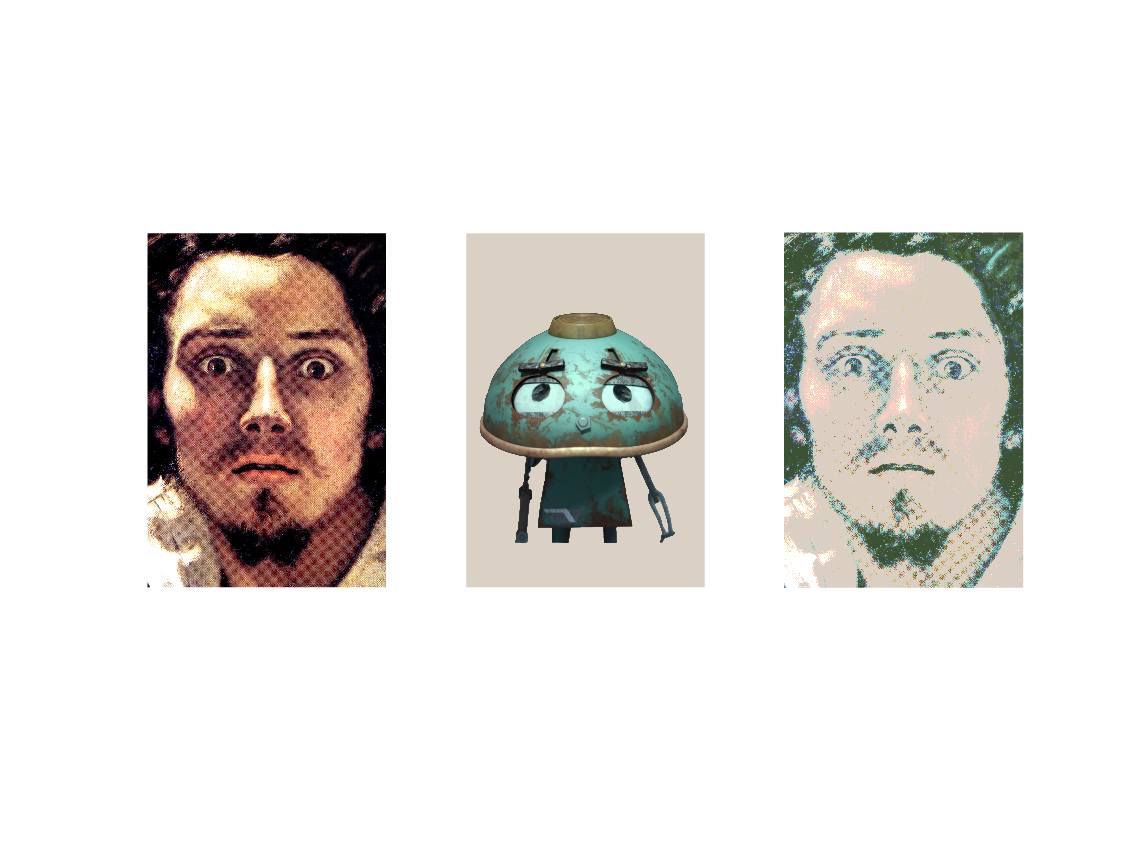

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%    Generate an image from img1 with a similar histogram as a reference %%
%    image img2                                                          %%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

[name1, name2, folder]  = ImgUI(); % dialog box for selecting images

im1 = imread(strcat(folder,'/',name1)); % the image to be equalized
im2 = imread(strcat(folder,'/',name2)); % the reference image
out1 = imhistmatch(im1, im2); % the equalized image usig the matching histogram function
%out2 = imhistmatch(im3,im2);
%out3 = imhistmatch(out2,out1);
figure; 
sb1 = subplot(1,3,1);
%sb1.Position  =  sb1.Position + [0 0 0.1 0];
imshow(im1);
sb2 = subplot(1,3,2);
%sb2.Position  =  sb2.Position + [0 0 0.1 0];
imshow(im2);
sb3 = subplot(1,3,3);
%sb3.Position  =  sb3.Position + [0 0 0.1 0];
imshow(out1);


% subplot(1,6,4);
% imshow(im3);
% subplot(1,6,5);
% imshow(out2);
% subplot(1,6,6);
% imshow(out3);